J=0.0006399

J = 6.3990e-04

B=0.0169

B = 0.0169

K=362

K = 362

%tau=0.05
k_e=0

k_e = 0

b_e=10

b_e = 10

m_e=10

m_e = 10

P_m=10

P_m = 10

I_m=2000

I_m = 2000

% passivityCheck
% eval(d_4s)
% eval(d_6s)
% eval(d_4s^2-d_2s*4*d_6s)
% eval(beta)
% eval(routh)
% eval(xi)
% eval(c_1)
% eval(m_e_lower)
% eval(m_e_max)
% eval(K_min)
% eval(k_e_min)
clear s; syms s

phy=tf([K],[1, 0]);
[nume dene]=numden((Y_e));
nume=[1 0];
dene=eval(fliplr(coeffs(dene,s)));
env=tf(nume,dene);
zenv=tf(dene,nume)


zenv =
 
  10 s^2 + 10 s
  -------------
        s
 
Continuous-time transfer function.



syms s;
x=s

$$x = s$$

[numa dena]=numden(eval(Z2));
numa=eval(fliplr(coeffs(numa,s)));
dena=eval(fliplr(coeffs(dena,s)));
sys=tf(numa,[dena 0]);
[numa dena]=numden(eval(1/Z3));
numa=eval(fliplr(coeffs(numa,s)));
dena=eval(fliplr(coeffs(dena,s)));
sys2=tf(numa,[dena 0]);
P_m=10;
[numa dena]=numden(eval(Z2));
numa=eval(fliplr(coeffs(numa,s)));
dena=eval(fliplr(coeffs(dena,s)));
sys2=tf(numa,[dena 0]);
P_m=100

P_m = 100

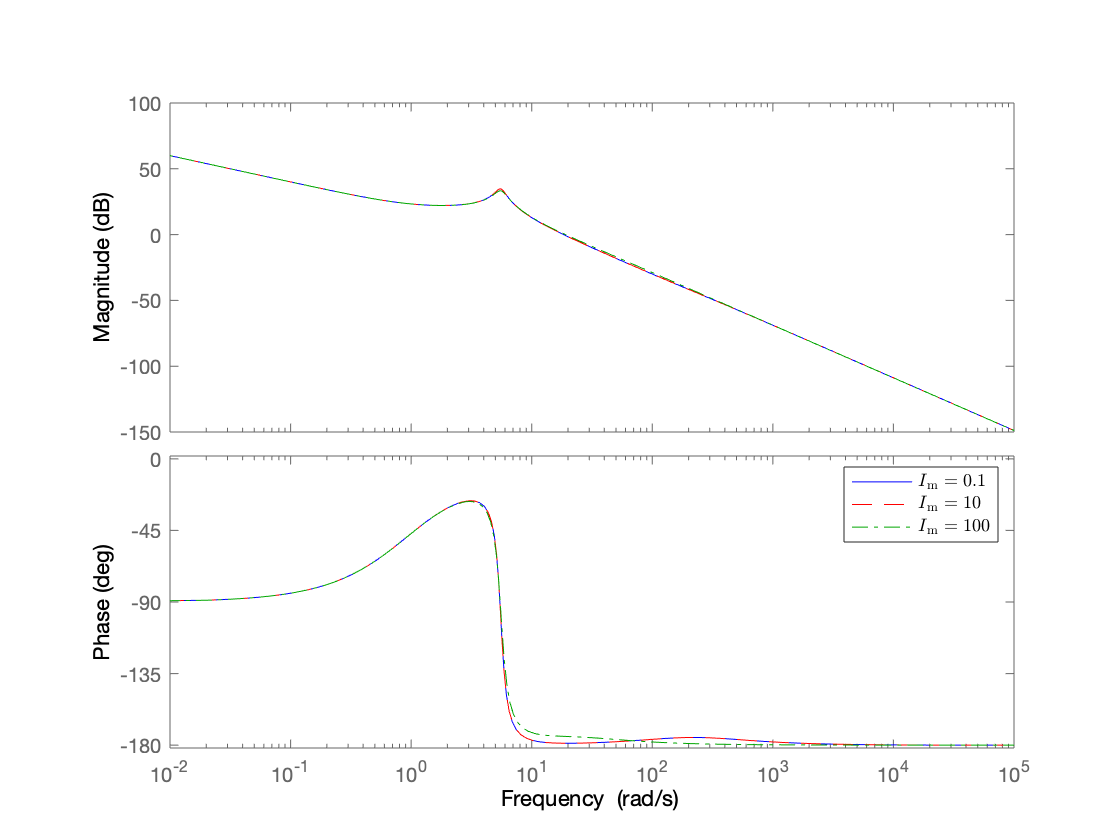

[numa dena]=numden(eval(Z2));
numa=eval(fliplr(coeffs(numa,s)));
dena=eval(fliplr(coeffs(dena,s)));
sys3=tf(numa,[dena 0]);
figure
bode(sys,'b-',sys2,'r--',sys3,'g-.')
h = legend('$P\_{\mathrm{m}}=0.1$', '$P\_{\mathrm{m}}=10$','$P\_{\mathrm{m}}=100$'); set(h, 'Interpreter', 'latex');
title('')
% %% I_m is below
% [numa dena]=numden(eval(Z2));
% numa=eval(fliplr(coeffs(numa,s)));
% dena=eval(fliplr(coeffs(dena,s)));
% sys=tf(numa,[dena 0]);
% I_m=10;
% [numa dena]=numden(eval(Z2));
% numa=eval(fliplr(coeffs(numa,s)));
% dena=eval(fliplr(coeffs(dena,s)));
% sys2=tf(numa,[dena 0]);
% I_m=100
% [numa dena]=numden(eval(Z2));
% numa=eval(fliplr(coeffs(numa,s)));
% dena=eval(fliplr(coeffs(dena,s)));
% sys3=tf(numa,[dena 0]);
% figure
% bode(sys,'b-',sys2,'r--',sys3,'g-.')

h = legend('$I\_{\mathrm{m}}=0.1$', '$I\_{\mathrm{m}}=10$','$I\_{\mathrm{m}}=100$'); set(h, 'Interpreter', 'latex');

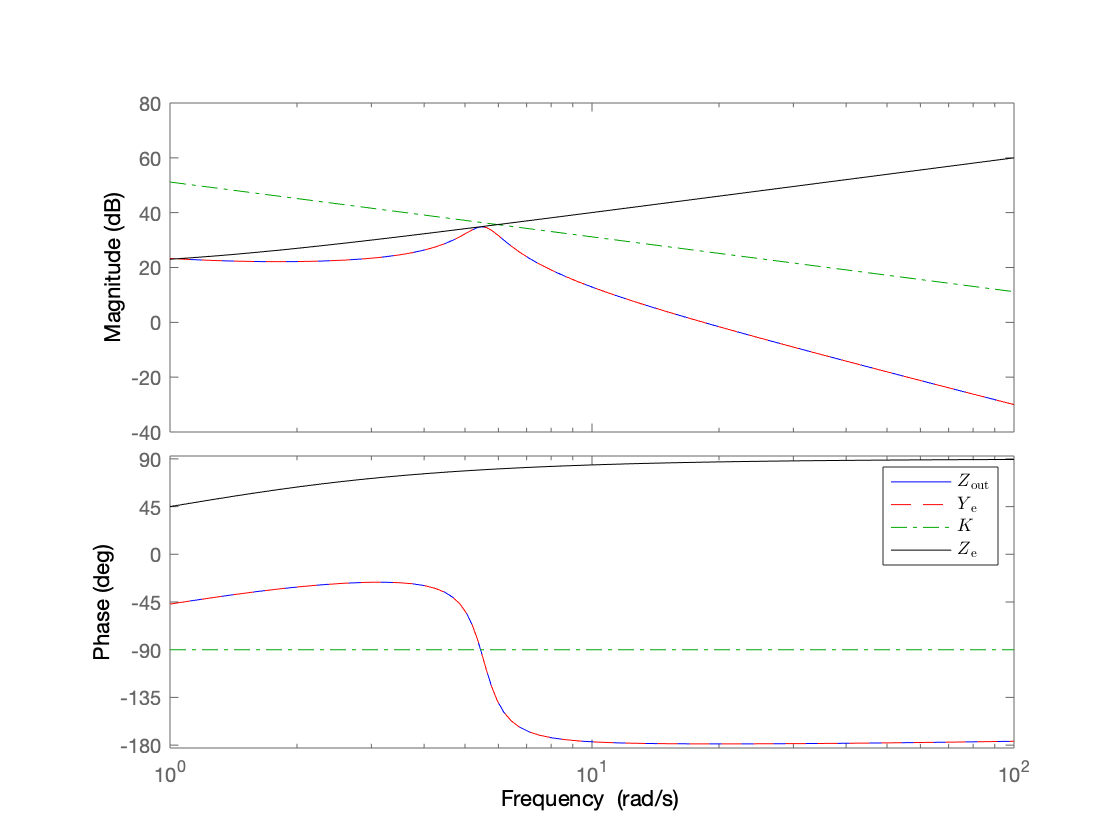

bode(sys,'b-',sys2,'r--',phy,'g-.',zenv,'k',{1,100})
title('')
h = legend('$Z\_{\mathrm{out}}$', '$Y\_{\mathrm{e}}$', '$K$', '$Z\_{\mathrm{e}}$'); set(h, 'Interpreter', 'latex');

title('')
% figure
% step(sys)
% nyquist(sys)
% rlocus(sys)